Matlab code for the Course: **Modelling and Simulation Mechatronics System (2020)**

by Enrico Bertolazzi and Francesco Biral

Dipartimento di Ingegneria Industriale

Università degli Studi di Trento

email: [enrico.bertolazzi@unitn.it](mailto:enrico.bertolazzi@unitn.it)

#### Initialize by cleaning memory and widows

close all;

#### Initialize parameters of the model and instantiate model class

mass    = 1;
gravity = 9.81;
ell     = 1;
DAE     = PendulumDAE( mass, gravity, ell );

#### Initialize the solver class

solver = DAE3TaylorSolver();
solver.setDAE( DAE );

#### Initialize the range where solution is computed and initial conditions

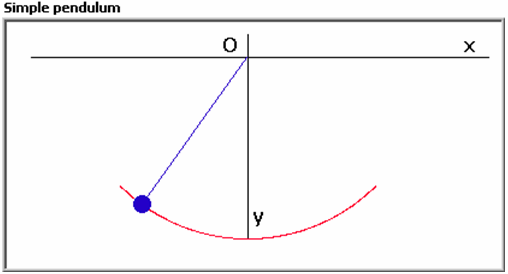

T     = 5;
DT    = 0.01;
theta = pi/2;
x     = ell*sin(theta);
y     = ell*cos(theta);
u     = 0;
v     = 0;
p0    = [ x, y ];
v0    = [ u, v];

#### Advance the DAE (using not stabilized index-1 DAE)

tt  = 0:DT:T;
tt1 = 0:DT/2:T;
tt2 = 0:DT/10:T;
[p, v]  = solver.advance_simple( tt,  p0, v0 );
[p1,v1] = solver.advance_simple( tt1, p0, v0 );
[p2,v2] = solver.advance_simple( tt2, p0, v0 );

#### plot solution

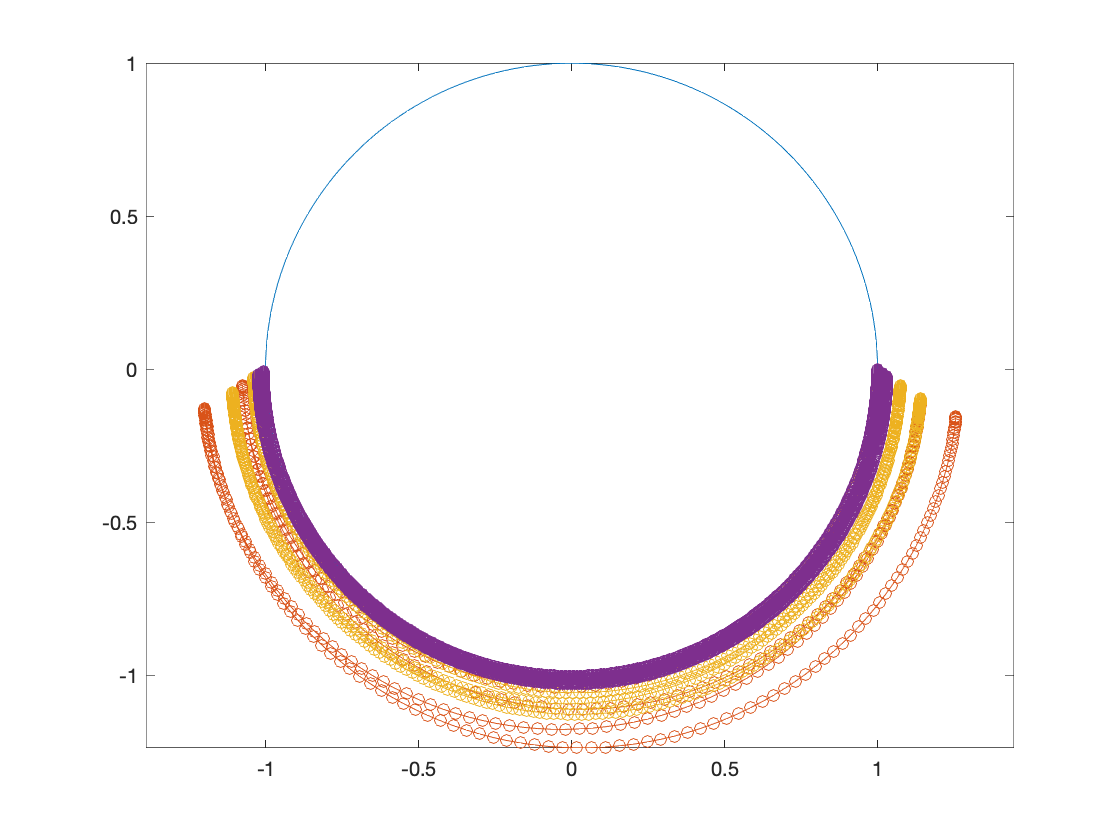

plot( sin(0:pi/100:2*pi), cos(0:pi/100:2*pi), 'Linewidth', 0.2);
hold on;
plot( p(1,:),  p(2,:),  'o-', 'Linewidth', 0.2);
plot( p1(1,:), p1(2,:), 'o-', 'Linewidth', 0.2);
plot( p2(1,:), p2(2,:), 'o-', 'Linewidth', 0.2);
hold off;
axis equal;

#### Plot animation

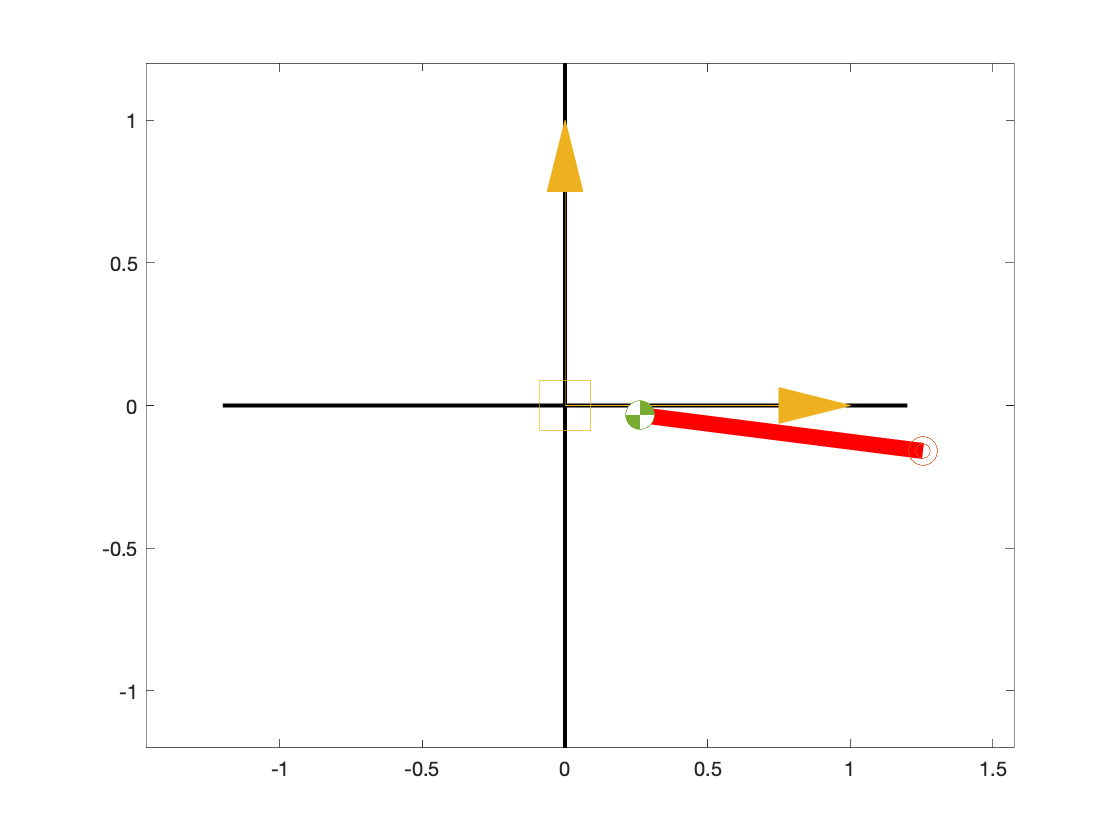

figure();
for k=1:5:size(p,2)
  DAE.plot(p(:,k));
  axis equal
  drawnow;
end

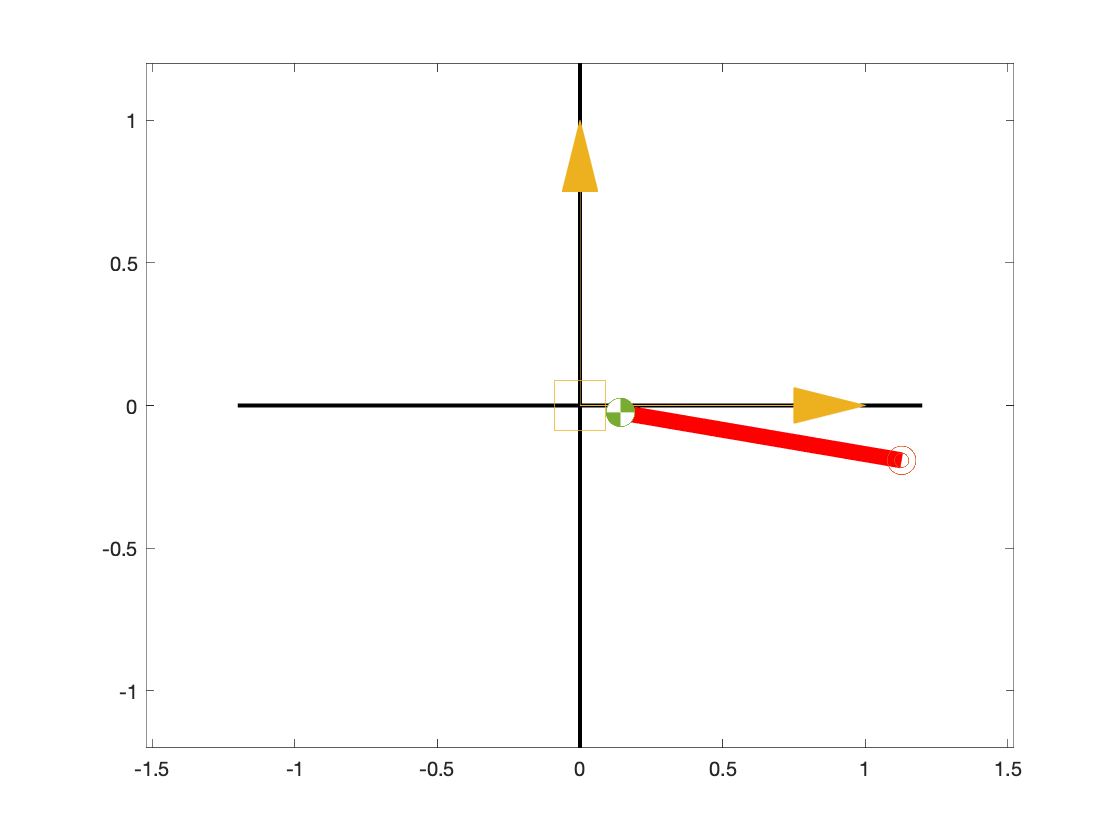

figure();
for k=1:10:size(p1,2)
  DAE.plot(p1(:,k));
  axis equal
  drawnow;
end

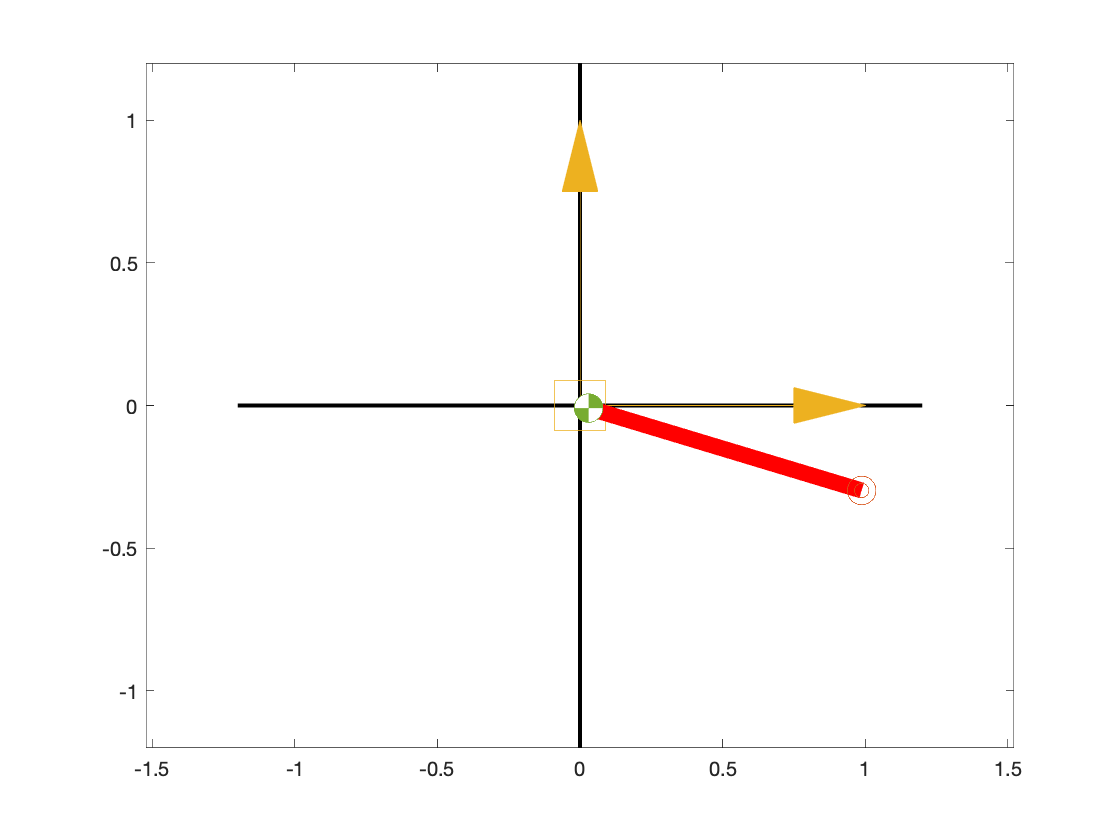

figure();
for k=1:20:size(p2,2)
  DAE.plot(p2(:,k));
  axis equal
  drawnow;
end

#### Advance the DAE (using stabilized index-1 DAE)

set parameter

eta   = 0.5;
omega = 10;

advance

tt  = 0:DT:T;
tt1 = 0:DT/2:T;
tt2 = 0:DT/10:T;
[ps, vs ] = solver.advance_Baumgarte( tt, p0, v0, eta, omega );
[ps1,vs1] = solver.advance_Baumgarte( tt1, p0, v0, eta, omega );
[ps2,vs2] = solver.advance_Baumgarte( tt2, p0, v0, eta, omega );

#### plot solution

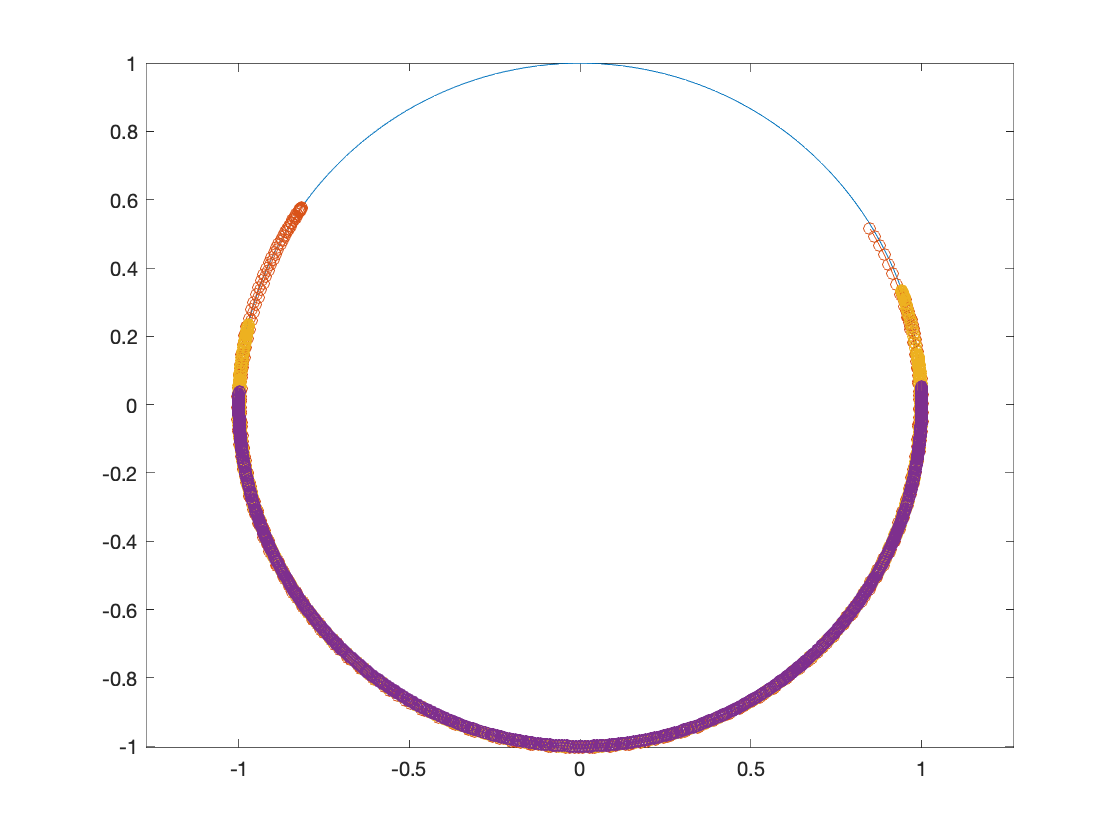

figure();
plot( sin(0:pi/100:2*pi), cos(0:pi/100:2*pi), 'Linewidth', 0.2);
hold on;
plot( ps(1,:),  ps(2,:),  'o-', 'Linewidth', 0.2 );
plot( ps1(1,:), ps1(2,:), 'o-', 'Linewidth', 0.2 );
plot( ps2(1,:), ps2(2,:), 'o-', 'Linewidth', 0.2 );
hold off;
axis equal;

#### Plot animation

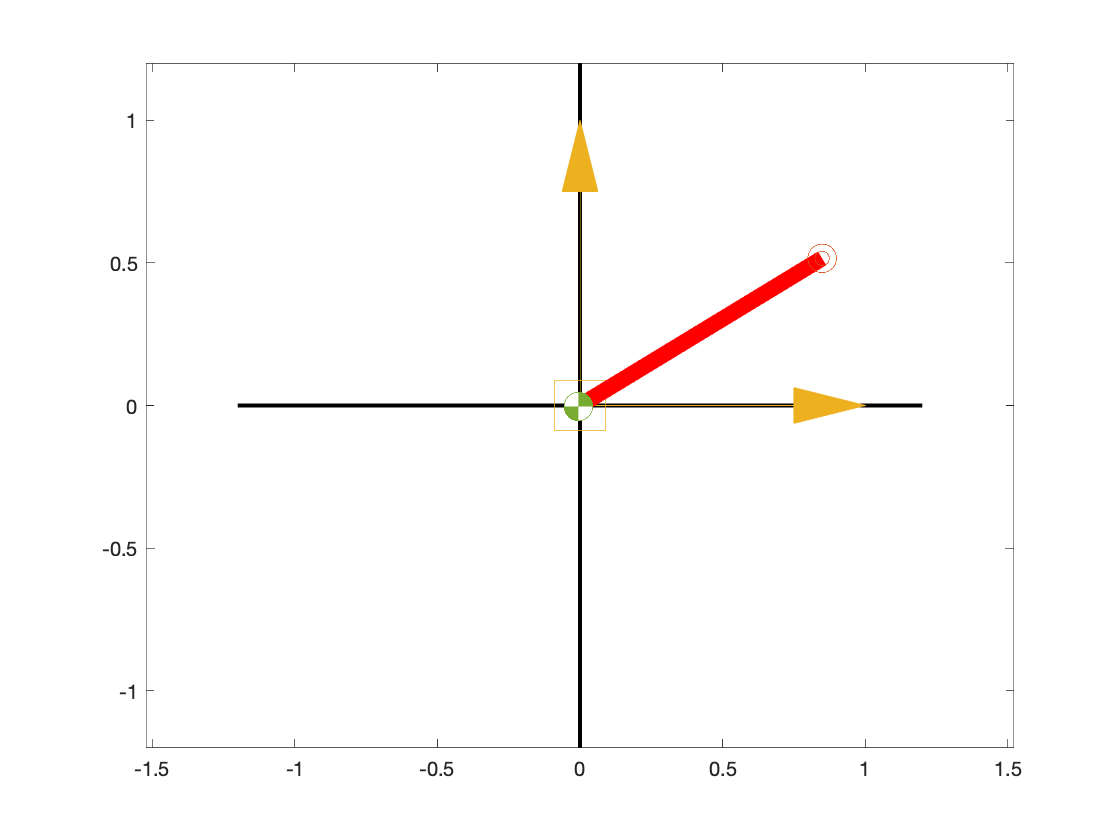

figure();
for k=1:5:size(ps,2)
  DAE.plot(ps(:,k));
  axis equal
  drawnow;
end

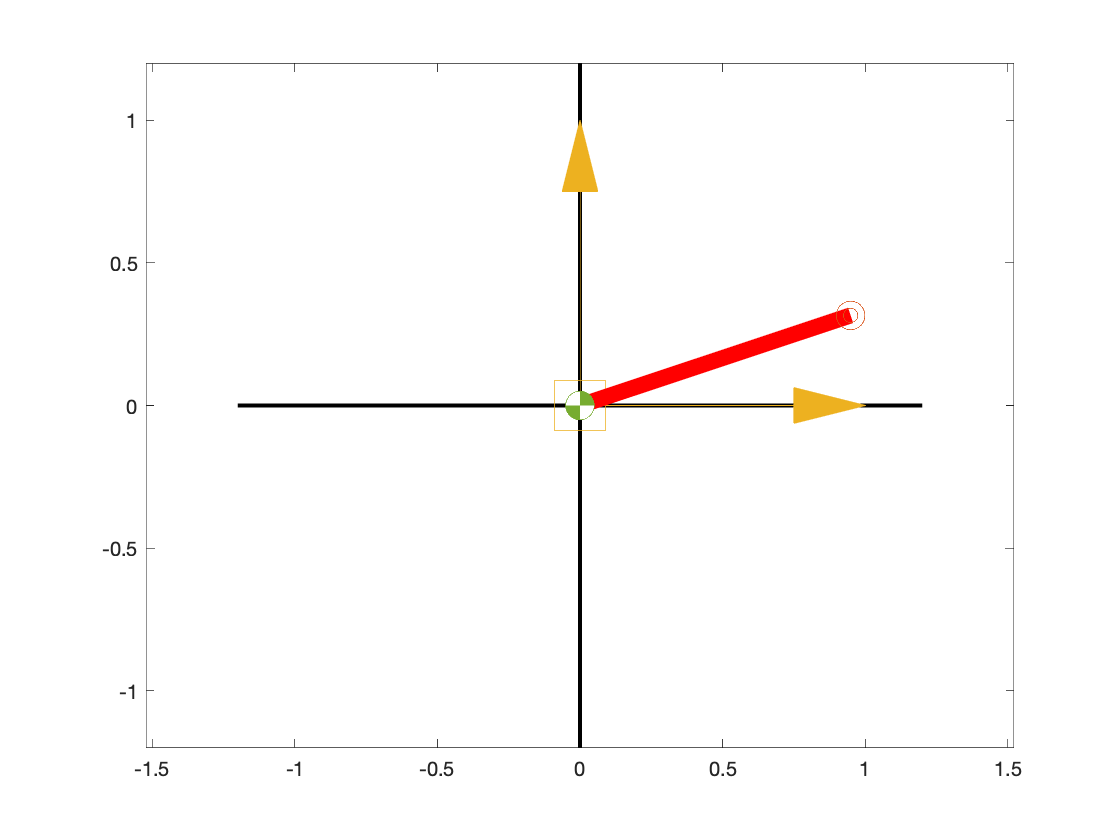

figure();
for k=1:10:size(ps1,2)
  DAE.plot(ps1(:,k));
  axis equal
  drawnow;
end

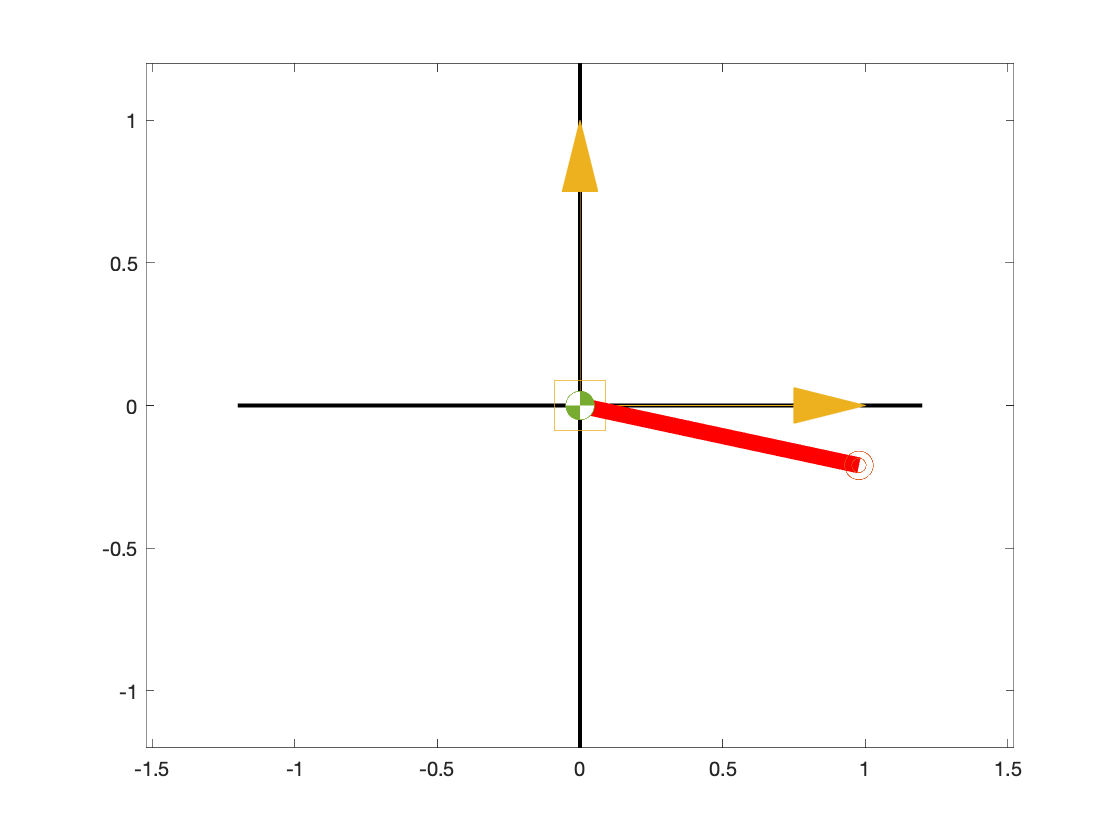

figure()
for k=1:20:size(ps2,2)
  DAE.plot(ps2(:,k));
  axis equal
  drawnow;
end